load('bh_SAVED_LIN_PLANT.mat')
size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


## Exploring Controllability:

Our current linearised plant has the following shape:

size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


Let's explore either BALANCING or REDUCING this linear system

%NEW_LIN_PLANT = my_LIN_PLANT;
%[NEW_LIN_PLANT,g,T,Ti] = balreal(my_LIN_PLANT);
[NEW_LIN_PLANT, U_T_mat] = minreal(my_LIN_PLANT);

2 states removed.


The NEW system shape is:

size(NEW_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 16 states.


A = NEW_LIN_PLANT.A;
B = NEW_LIN_PLANT.B;
C = NEW_LIN_PLANT.C;
D = NEW_LIN_PLANT.D;

## Control design:

We'll use the approach described by the LQI() function, ie::

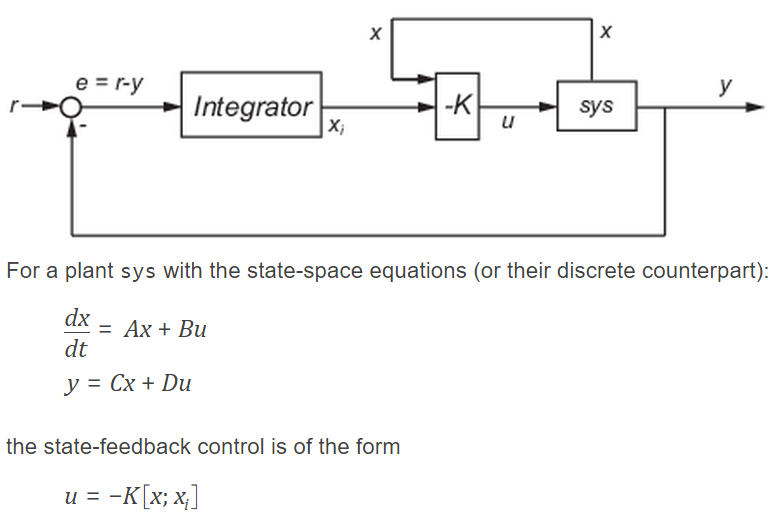

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

tmp = 1*[ones(1, Nx+Ny)];
Q   = diag(tmp); 
tmp = 1e4*[1,1,1,1];
R = diag(tmp); 

[K_new,~,~] = lqi(NEW_LIN_PLANT,Q,R,[])

K_new =    -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0003   -0.0003    0.4822   -0.0002    0.0001   -0.0987   -0.0000    0.0000   -0.0100
   -0.1326   -1.5281    0.2465   -0.1999    0.0000    0.0057   -0.0018   -0.0000    0.0000   -0.0393   -0.1455    0.1370    0.0002   -0.0102   -0.0280    0.0000    0.0000   -0.0100   -0.0000
   -0.0002    0.0062   -0.0010   -0.0010    0.0005    1.4724   -0.4775   -0.1326   -0.2826    0.0008    0.0261    0.0294    0.0000    0.0280   -0.0102   -0.0000    0.0100   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0071   -0.0171    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0052    0.0048    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000


What does the gain matrix K, look like?

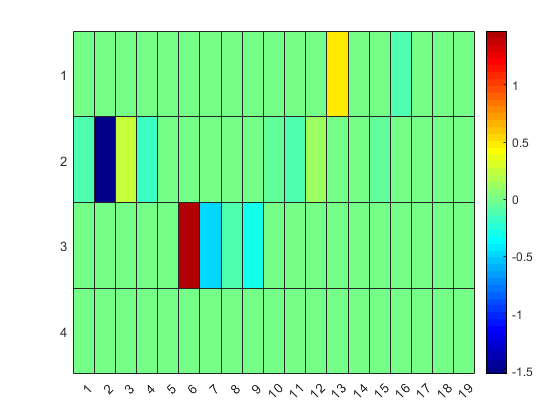

hfig = figure;
% colormap(hfig,jet)
% imagesc(K); colorbar
heatmap(K_new,'ColorMap', jet(50) );

What do the closed loop poles look like ?

A_hat = [  A,   zeros(Nx,Ny);
          -C,   zeros(Ny,Ny) ];
      
B_hat = [ B;
          zeros(Ny,Nu) ];
p_lqi = esort( pole( ss((A_hat-B_hat*K_new),[],[],[]) ) )

p_lqi =   -0.1035 + 0.1767i
  -0.1035 - 0.1767i
  -0.2027 + 0.0000i
  -0.8660 + 0.5000i
  -0.8660 - 0.5000i
  -0.8660 + 0.5000i
  -0.8660 - 0.5000i
  -0.8857 + 0.4997i
  -0.8857 - 0.4997i
  -1.1142 + 1.8553i
